clear
close all
clc

## 1) Model definition

Y_v_nom = -0.1068;    % [1/s]
Y_p_nom = 0.1192;     % [m/(s rad)]
L_v_nom = -5.9755;    % [rad s/m]
L_p_nom = -2.6478;    % [1/s]

Y_d_nom = -10.1647;   % [m/s^2]
L_d_nom = 450.7085;   % [rad/s^2]

unc_Y_v = 3*4.26;
unc_Y_p = 3*2.03;
unc_L_v = 3*1.83;
unc_L_p = 3*2.01;
unc_Y_d = 3*1.37;
unc_L_d = 3*0.81;

% Stability Derivatives
Y_v = ureal('Y_v',Y_v_nom,'Perc',unc_Y_v);
Y_p = ureal('Y_p',Y_p_nom,'Perc',unc_Y_p);
% L_v = ureal('L_v',L_v_nom,'Perc',unc_L_v);
L_v = 0;
L_p = ureal('L_p',L_p_nom,'Perc',unc_L_p);

% Control Derivatives
Y_d = ureal('Y_d',Y_d_nom,'Perc',unc_Y_d);
L_d = ureal('L_d',L_d_nom,'Perc',unc_L_d);

g = 9.81;

% State Space Model
A = [Y_v Y_p g; L_v L_p 0; 0 1 0];
B = [Y_d L_d 0]';
C = [0 1 0; 0 0 1];
D = [0 0]';

% Uncertain Plant
sys_ld = ss(A,B,C,D);
sys_ld.u = '\delta_{lat}';
sys_ld.y = {'p','\phi'};

% Nominal Plant
sys_ld_nom = sys_ld.NominalValue


sys_ld_nom =
 
  A = 
            x1       x2       x3
   x1  -0.1068   0.1192     9.81
   x2        0   -2.648        0
   x3        0        1        0
 
  B = 
       \delta_{lat}
   x1        -10.16
   x2         450.7
   x3             0
 
  C = 
         x1  x2  x3
   p      0   1   0
   \phi   0   0   1
 
  D = 
         \delta_{lat}
   p                0
   \phi             0
 
Continuous-time state-space model.


sys_ld_nom.u = '\delta_{lat}';
sys_ld_nom.y = {'p','\phi'};

## 2) System analysis

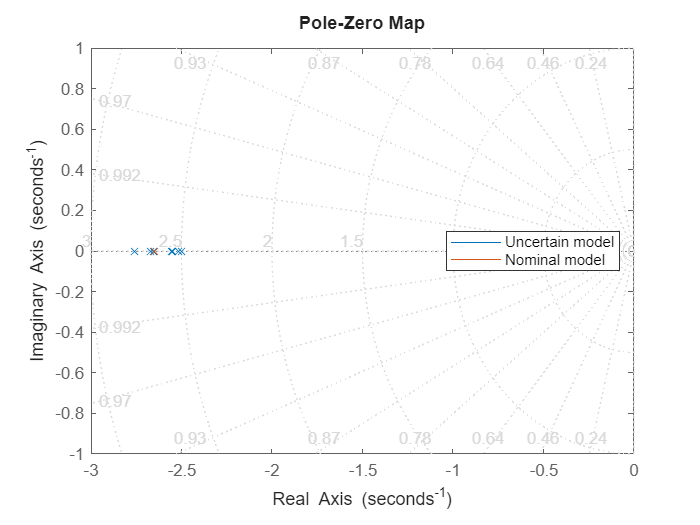

% From delta_lat to p
G_delta_lat_p_nom = tf(sys_ld_nom(1));
G_delta_lat_p = tf(sys_ld(1));

N = 10;                         
sysSamp = usample(sys_ld, N);     
G_delta_lat_pSamp = tf(sysSamp(1));

figure
pzplot(G_delta_lat_pSamp);
hold on 
pzplot(G_delta_lat_p_nom);
grid on                               
legend('Uncertain model','Nominal model','location','east')


z_delta_lat_p = tzero(G_delta_lat_p_nom)


z_delta_lat_p =

  0×1 empty double column vector



p_delta_lat_p = pole(G_delta_lat_p_nom)

p_delta_lat_p = -2.6478

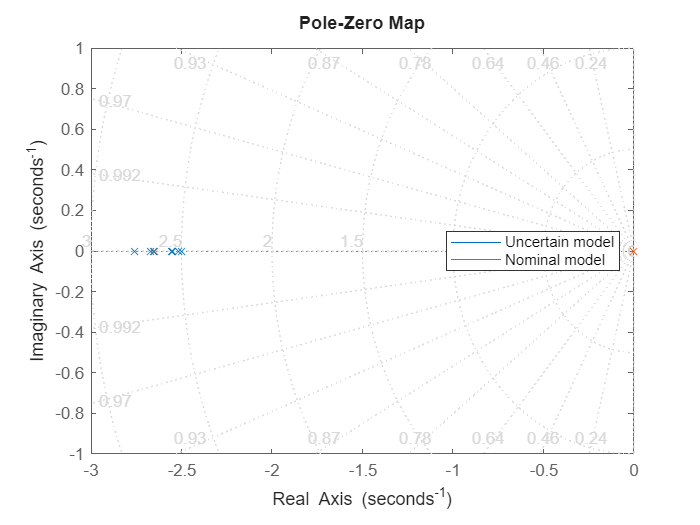

% From delta_lat to phi
G_delta_lat_phi_nom = tf(sys_ld_nom(2));
G_delta_lat_phi = tf(sys_ld(2));

G_delta_lat_phiSamp = tf(sysSamp(2));

figure
pzplot(G_delta_lat_phiSamp);
hold on 
pzplot(G_delta_lat_phi_nom);
grid on 
legend('Uncertain model','Nominal model','location','east')


z_delta_lat_phi = tzero(G_delta_lat_phi_nom)


z_delta_lat_phi =

  0×1 empty double column vector



p_delta_lat_phi = pole(G_delta_lat_phi_nom)

p_delta_lat_phi =          0
   -2.6478


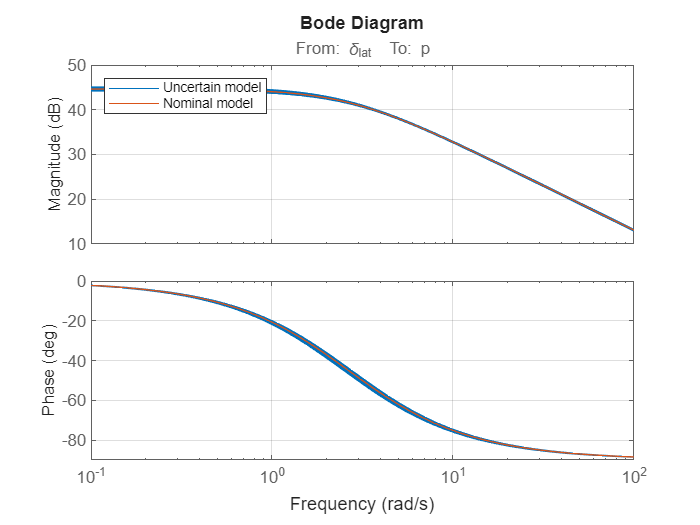

% Bode plot
figure 
bode(sys_ld(1))
hold on
bode(sys_ld_nom(1))
grid on
legend('Uncertain model','Nominal model','location','northwest')

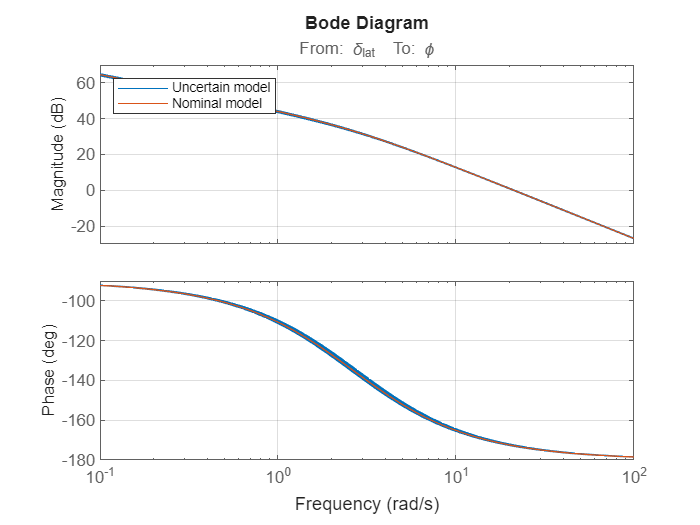

figure 
bode(sys_ld(2))
hold on
bode(sys_ld_nom(2))
grid on
legend('Uncertain model','Nominal model','location','northwest')

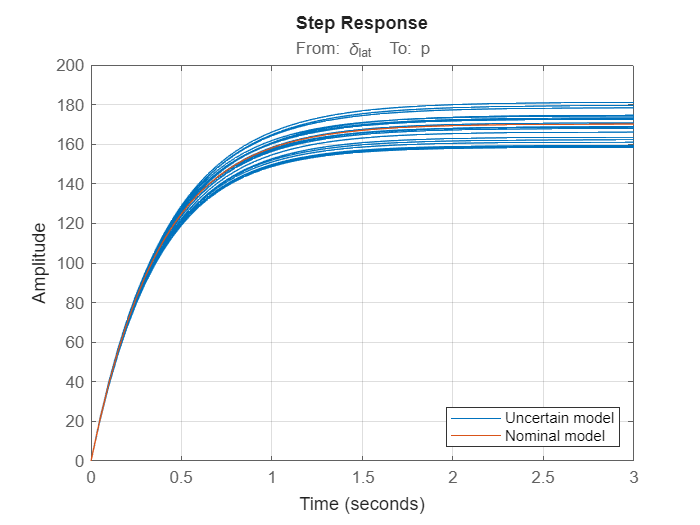

% Step response
figure
step(sys_ld(1),0:0.05:3);
hold on
step(sys_ld_nom(1),0:0.05:3);
grid on
legend('Uncertain model','Nominal model','location','southeast')

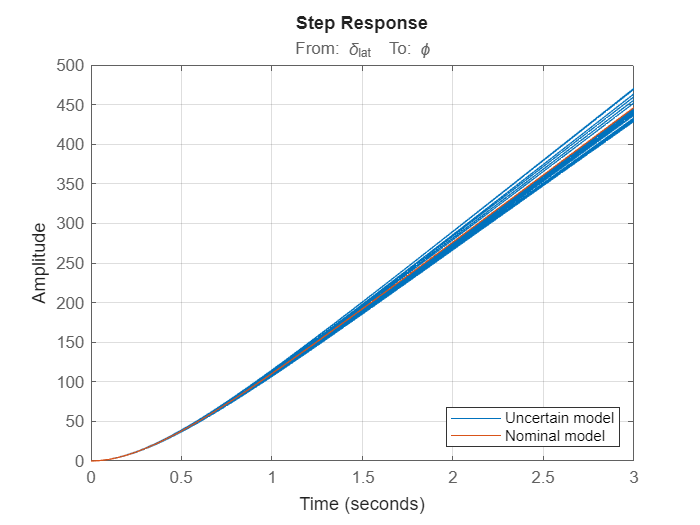

figure
step(sys_ld(2),0:0.05:3);
hold on
step(sys_ld_nom(2),0:0.05:3);
grid on
legend('Uncertain model','Nominal model','location','southeast')

## 3) Controller design

### a) Nominal perfomance

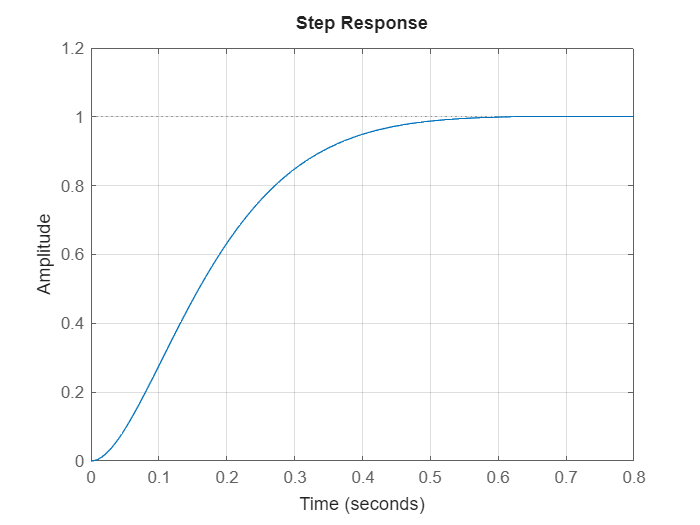

omega_n = 10;       % [rad/s]
xi = 0.9;

s = tf('s');
F_2 = omega_n^2/(s^2 + 2*s*xi*omega_n + omega_n^2);
S_2 = 1-F_2;

figure
step(F_2)
grid on

step_info_F_2 = stepinfo(F_2)

step_info_F_2 = struct with fields:
         RiseTime: 0.2883
    TransientTime: 0.4700
     SettlingTime: 0.4700
      SettlingMin: 0.9024
      SettlingMax: 1.0015
        Overshoot: 0.1524
       Undershoot: 0
             Peak: 1.0015
         PeakTime: 0.7215


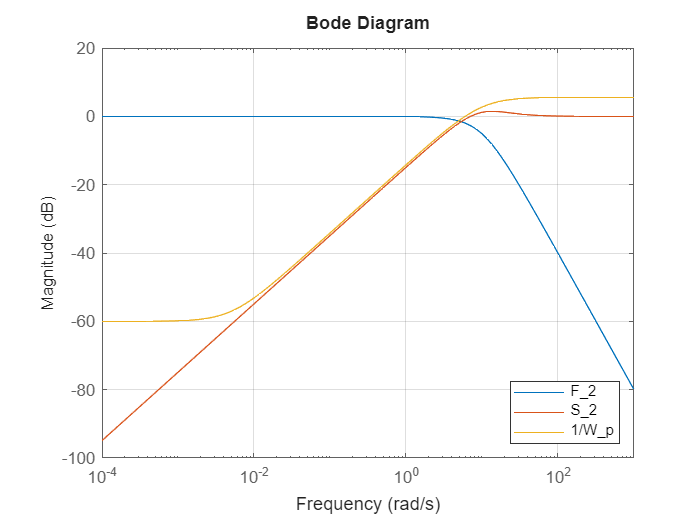

A = 1e-3;
M = 1.9;
omega_b = omega_n * 0.51;
W_p = (s/M + omega_b)/(s + A*omega_b);

figure
bodemag(F_2)
hold on
bodemag(S_2)
grid on
bodemag(1/W_p)
legend('F_2', 'S_2','1/W_p', 'location','southeast')

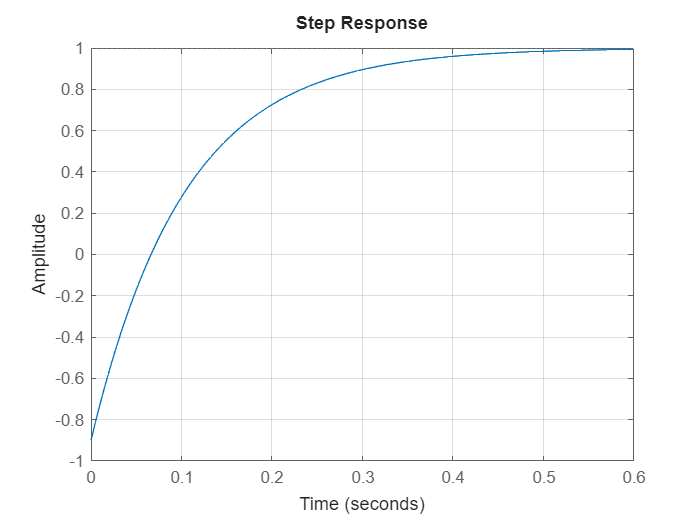


figure
F_step = tf(1-(1/W_p));
step(F_step)
grid on

stepinfo(F_step)

ans = struct with fields:
         RiseTime: 0.2267
    TransientTime: 0.4037
     SettlingTime: 0.4700
      SettlingMin: 0.8993
      SettlingMax: 0.9977
        Overshoot: 0
       Undershoot: 90.0901
             Peak: 0.9977
         PeakTime: 0.7556



figure
F_step = tf(1-1/W_p);
step(F_step)
grid on

stepinfo(F_step)

ans = struct with fields:
         RiseTime: 0.2267
    TransientTime: 0.4037
     SettlingTime: 0.4700
      SettlingMin: 0.8993
      SettlingMax: 0.9977
        Overshoot: 0
       Undershoot: 90.0901
             Peak: 0.9977
         PeakTime: 0.7556


### b) Control Effort limitation

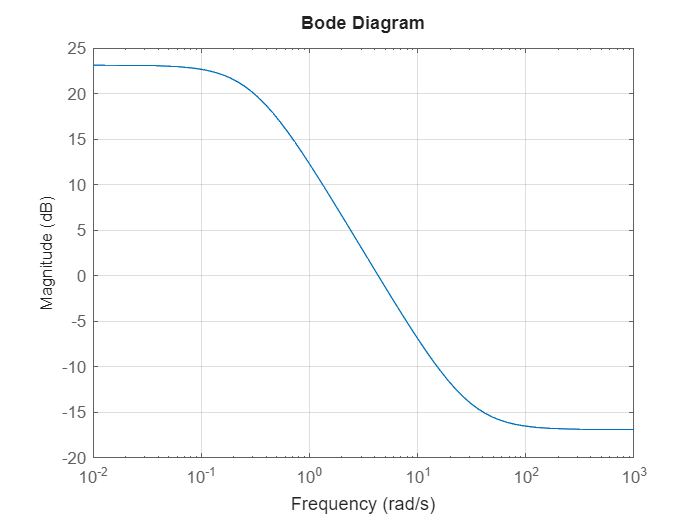

alpha = deg2rad(20)/0.05;
w_tau = 30;
W_q = alpha*(s+w_tau*1e-2)/(s+w_tau);

figure
bodemag(1/W_q)
grid on

% Controller blocks

R_phi = tunablePID('R_phi','P');

R_phi.u = 'e_\phi';
R_phi.y = 'p_0';

R_p = tunablePID2('R_p','PID');
R_p.c.Value = 0;
R_p.c.Free = false;
R_p.b.Value = 1;
R_p.b.Free = false;
R_p.Tf.Value = 0.02;
R_p.Tf.Free = false;

R_p.u = {'p_0','p'};
R_p.y = {'\delta_{lat}'};

% Close loop system for h_inf synthesis

W_q.u = '\delta_{lat}';
W_q.y = 'z_1';

W_p.u = 'e_\phi';
W_p.y = 'z_2';

SumOuter = sumblk('e_\phi = \phi_0 - \phi');

CL0 = connect(R_p, R_phi, sys_ld_nom, SumOuter, W_q, W_p, ...
    '\phi_0',{'z_1','z_2'},{'\delta_{lat}','e_\phi','\phi'});

Finally we can define options and run `hinfstruct`.

opt = hinfstructOptions('Display','final','RandomStart',20);

[CL_h,gamma,info] = hinfstruct(CL0,opt);

Final: Peak gain = 0.968, Iterations = 72
Final: Peak gain = 0.968, Iterations = 59
Final: Peak gain = 0.968, Iterations = 45
Final: Peak gain = 0.968, Iterations = 54
Final: Peak gain = 0.968, Iterations = 61
Final: Peak gain = 0.968, Iterations = 80
Final: Peak gain = 0.968, Iterations = 53
Final: Peak gain = 0.968, Iterations = 91
Final: Peak gain = 0.968, Iterations = 41
Final: Peak gain = 0.972, Iterations = 179
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.968, Iterations = 53
Final: Peak gain = 0.968, Iterations = 67
Final: Peak gain = 0.972, Iterations = 150
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Peak gain = 0.968, Iterations = 96
Final: Peak gain = 0.972, Iterations = 54
       Some closed-loop poles are marginally stable (decay rate near 1e-07)
Final: Failed to enforce closed-loop stability (max Re(s) = -1e-07)
Final: Peak gain = 0.972, Iterations = 38
       Some closed-loop poles 


showTunable(CL_h)

R_p =
 
                       1                s    
  u = Kp (b*r-y) + Ki --- (r-y) + Kd -------- (c*r-y)
                       s              Tf*s+1 

  with Kp = 0.0179, Ki = 0.0968, Kd = -0.000913, Tf = 0.02, b = 1, c = 0
 
Name: R_p
Continuous-time 2-DOF PIDF controller in parallel form.
-----------------------------------
R_phi =
 
  Kp = 5.27
 
Name: R_phi
P-only controller.


F = getIOTransfer(CL_h,'\phi_0','\phi');
S = getIOTransfer(CL_h,'\phi_0','e_\phi');
Q = getIOTransfer(CL_h,'\phi_0','\delta_{lat}');
L = F / (1-F);

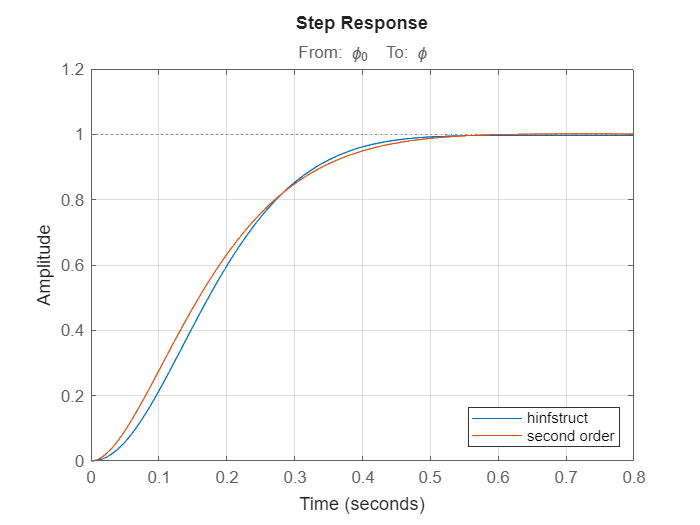

figure
step(F)
hold on
step(F_2)
grid on
legend('hinfstruct','second order', 'location','southeast')


stepinfo(F)

ans = struct with fields:
         RiseTime: 0.2656
    TransientTime: 0.4418
     SettlingTime: 0.4418
      SettlingMin: 0.9046
      SettlingMax: 0.9965
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9965
         PeakTime: 0.6099


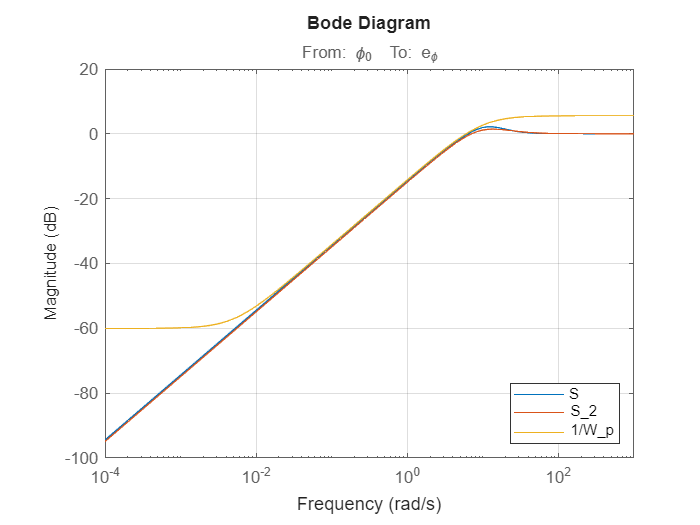

figure
bodemag(S)
hold on
grid on
bodemag(S_2)
bodemag(1/W_p)
legend('S', 'S_2','1/W_p', 'location','southeast')

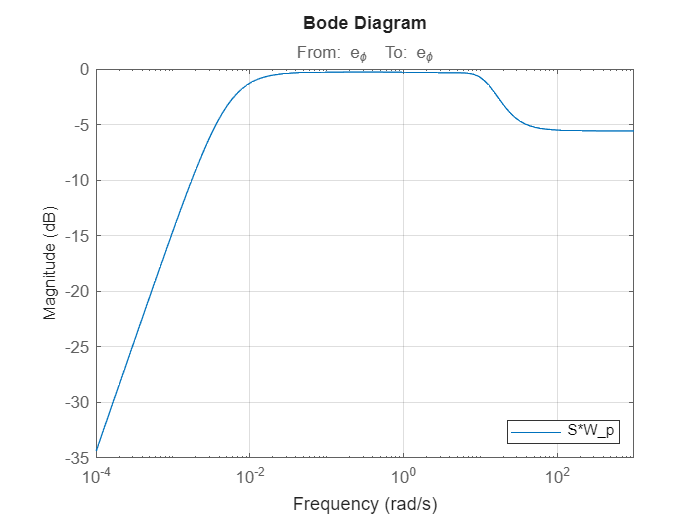


figure
bodemag(S*W_p)
legend('S*W_p', 'location','southeast')
grid on

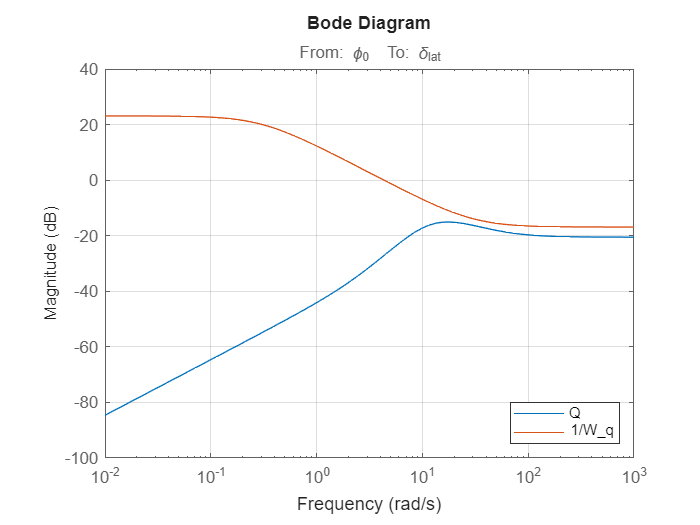

figure
bodemag(Q)
grid on
hold on
bodemag(1/W_q)
legend('Q','1/W_q', 'location','southeast')

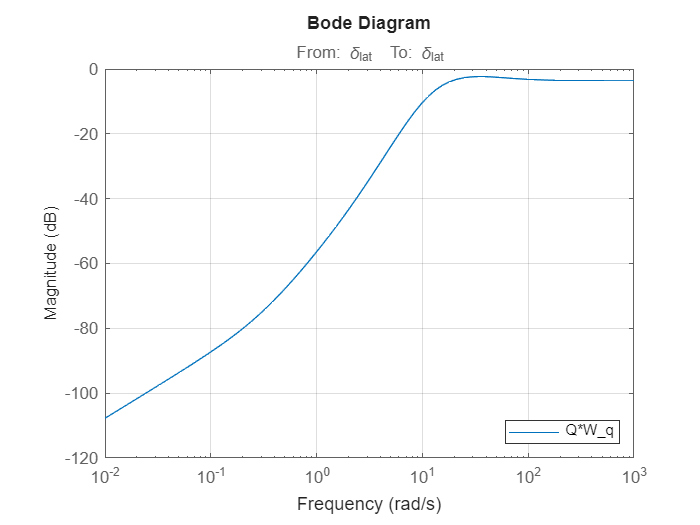


figure
bodemag(Q*W_q)
legend('Q*W_q', 'location','southeast')
grid on

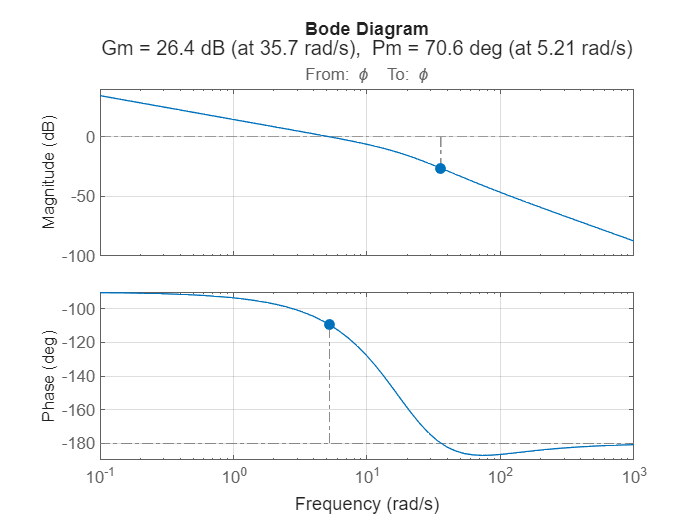

figure
margin(L)
grid on

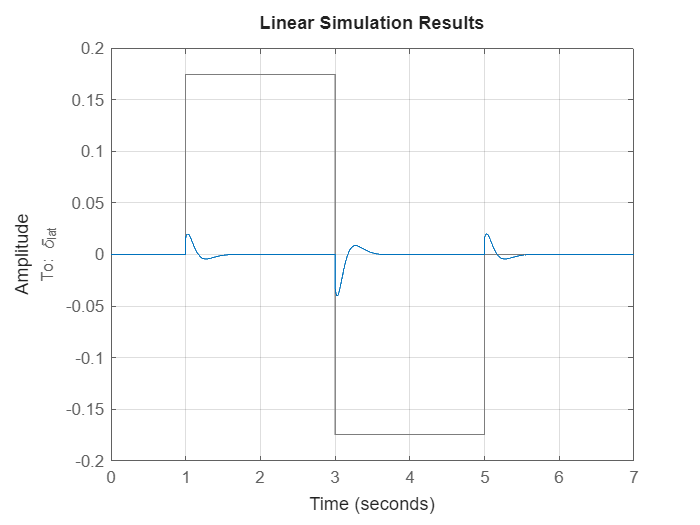

t = linspace(0,7,10^4);
u = 0*(t<=1) + 10*(t>1 & t<= 3) - 10*(t>3 & t<= 5) + 0*(t>5);
u = deg2rad(u);

figure
lsim(Q,u,t);
hold on
grid on

max_effort = -max(abs(lsim(Q,u,t)))

max_effort = -0.0398

## 4) Robust stability with multiplicative uncertainty

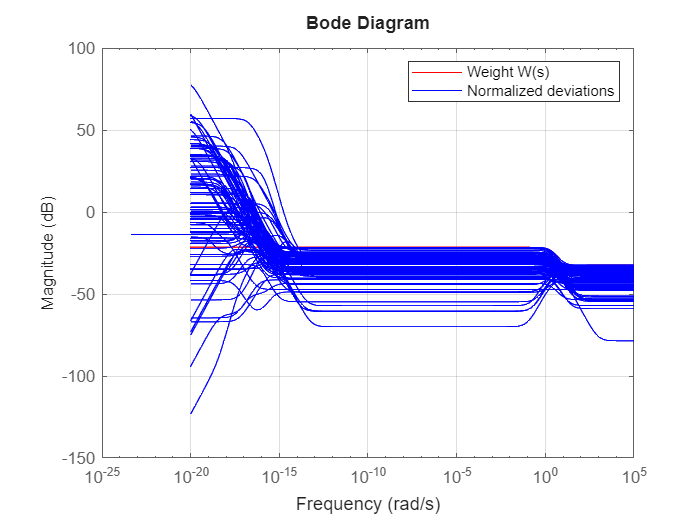

sys_ld_array = usample(sys_ld(2),100);
[~,Info] = ucover(sys_ld_array,sys_ld_nom(2),3);

W = Info.W1;

figure
bodemag(W,'r')
hold on
bodemag((sys_ld_nom(2)-sys_ld_array)/sys_ld_nom(2),'b')
grid on
legend('Weight W(s)', 'Normalized deviations','location','northeast')

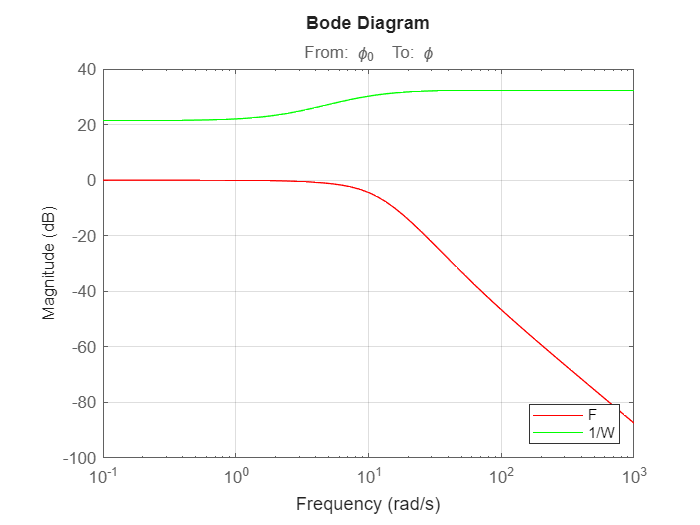

figure
bodemag(F,'r',1/W,'g')
grid on
legend('F','1/W','location','southeast')

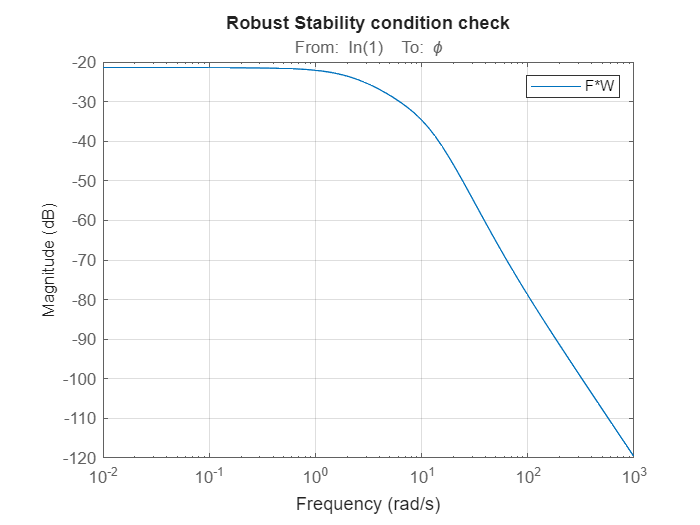


figure
bodemag(F*W)
grid on
title('Robust Stability condition check')
legend('F*W')

### 5) Robust performance with multiplicative uncertainty

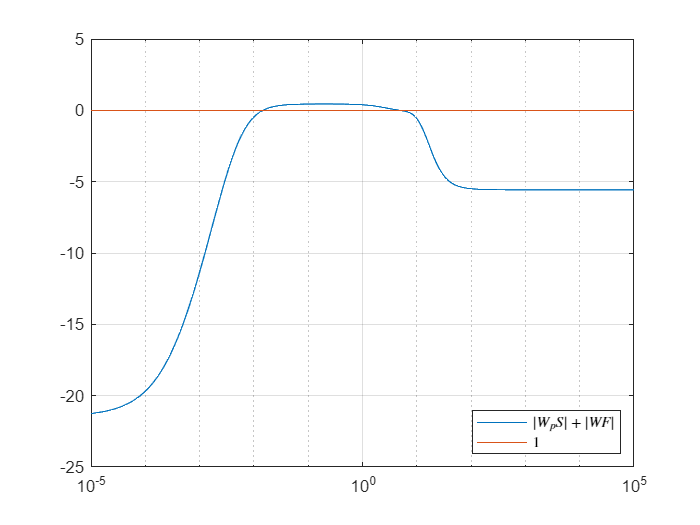

w = logspace(-5,5,500);

FW = bode(F*W,w); 
SW = bode(S*W_p,w);

figure
semilogx(w, 20*log10(squeeze(FW)+squeeze(SW)))
hold on 
semilogx(w,20*log10(w./w))
grid on
legend('$|W_p S|+|W F|$','$1$','interpreter','latex', 'location','southeast')

can't obtain robust performance !!!

## 6) Robust stability with M-Delta form

R_p = CL_h.Blocks.R_p;
R_p.u = {'p_0','p'};
R_p.y = {'\delta_{lat}'};
R_phi = CL_h.Blocks.R_phi;
R_phi.y = 'p_0';
R_phi.u = 'e_\phi';

SumOuter = sumblk('e_\phi = \phi_0 - \phi');

CL = connect(SumOuter,R_phi,R_p,sys_ld,'\phi_0',{'\phi','p','\delta_{lat}'});

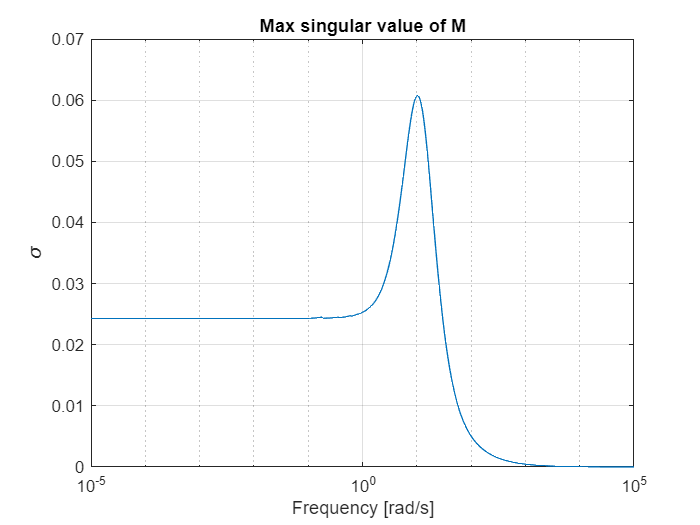

[M_aug,Delta,BlkStruct] = lftdata(CL);
szDelta = size(Delta);
M = M_aug(1:szDelta(2),1:szDelta(1));

w = logspace(-5,5,500);
msvd = zeros(size(w));
options = optimset('Display','off','Algorithm','levenberg-marquardt');
D0 = (1+1j)*ones(szDelta(1), 1);

% compute
for i=1:size(w, 2)
    N = evalfr(tf(M),1j*w(i));
    f = @(D) norm(diag(D)*N*diag(1./D));
    D = fsolve(f, D0, options);
    D0 = D;
    msvd(i)=f(D);
end

figure
semilogx(w, msvd)
grid on
xlabel('Frequency [rad/s]')
ylabel('\sigma')
title('Max singular value of M')


M_poles = pole(M)

M_poles =  -16.7613 + 0.0000i
  -9.2115 + 7.3072i
  -9.2115 - 7.3072i
  -4.9574 + 0.0000i


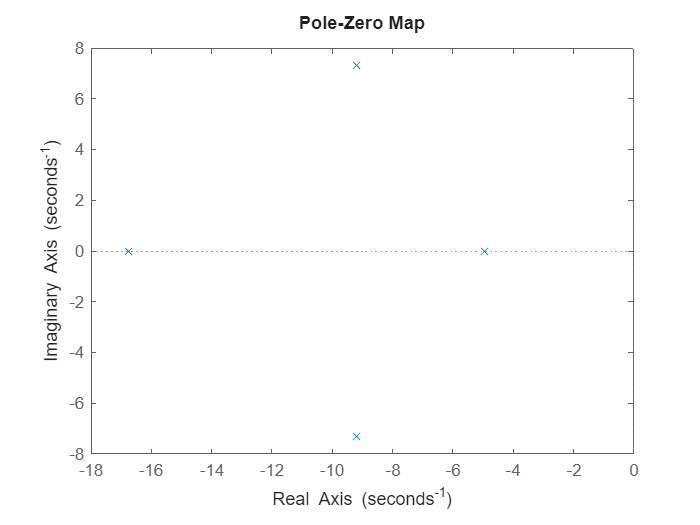

pzplot(M)

## 7) Robust performance in M-Delta form

R_p = CL_h.Blocks.R_p;
R_p.u = {'p_0','p'};
R_p.y = {'\delta_{lat}'};
R_phi = CL_h.Blocks.R_phi;
R_phi.y = 'p_0';
R_phi.u = 'e_\phi';

SumOuter = sumblk('e_\phi = \phi_0 - d_\phi');
SumDisturbance = sumblk('d_\phi = \phi + d');

delta_perf = ureal('delta_perf',0,'Range',[-1, 1]);
W_p_dist = W_p * delta_perf;
W_p_dist.u = 'd_\phi';
W_p_dist.y = 'd';

CL_rp = connect(SumOuter,SumDisturbance,R_phi,R_p,W_p_dist,sys_ld,'\phi_0',{'\phi','p','\delta_{lat}', 'd'});

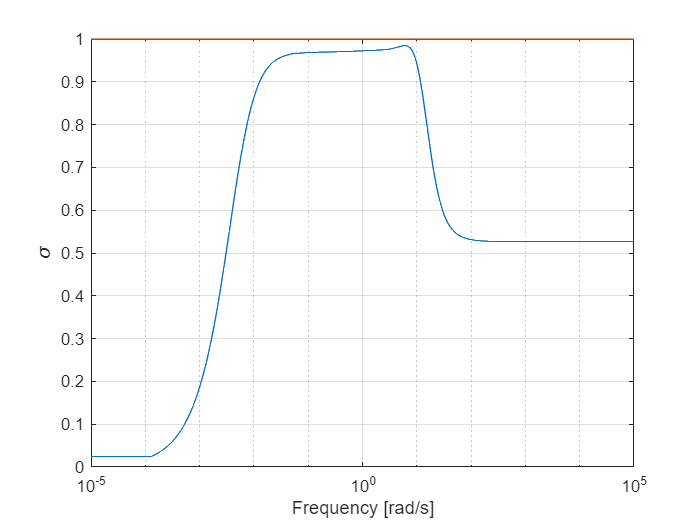

[M_aug,Delta,~] = lftdata(CL_rp);
szDelta = size(Delta);
M = M_aug(1:szDelta(2),1:szDelta(1));

w = logspace(-5,5,500);
msvd = zeros(size(w));
options = optimset('Display','off','Algorithm','levenberg-marquardt');
D0 = (1+1j)*ones(szDelta(1), 1);

for i=1:size(w, 2)
    N = evalfr(tf(M),1j*w(i));
    f = @(D) norm(diag(D)*N*diag(1./D));
    D = fsolve(f, D0, options);
    D0 = D;
    msvd(i)=f(D);
end

figure
semilogx(w, msvd)
hold on 
semilogx(w,w./w)
grid on
xlabel('Frequency [rad/s]')
ylabel('\sigma')


figure
loglog(w, msvd)
hold on 
S_rs = getIOTransfer(CL_h,'\phi_0','e_\phi');
loglog(w, squeeze(bode(S_rs*W_p, w)))
loglog(w,w./w)
grid on
legend('Msvd','S*W_p', '1','location','southeast')
xlabel('Frequency [rad/s]')
ylabel('\sigma')

M_poles_RS = pole(M)

M_poles_RS =  -16.7613 + 0.0000i
  -9.2115 + 7.3072i
  -9.2115 - 7.3072i
  -4.9574 + 0.0000i
  -0.0051 + 0.0000i


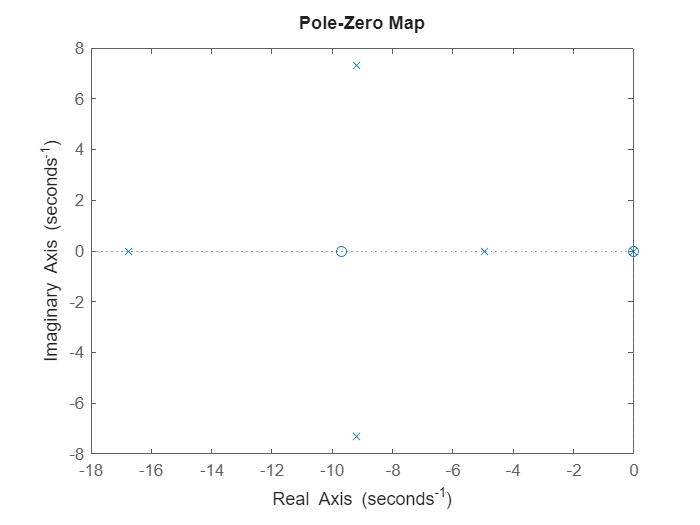

pzplot(M)

## 8) Sampled closed loop graphs

sampled_CL = usample(CL, 200);

F = getIOTransfer(sampled_CL,'\phi_0','\phi');
S = 1-F;
Q = getIOTransfer(sampled_CL,'\phi_0','\delta_{lat}');

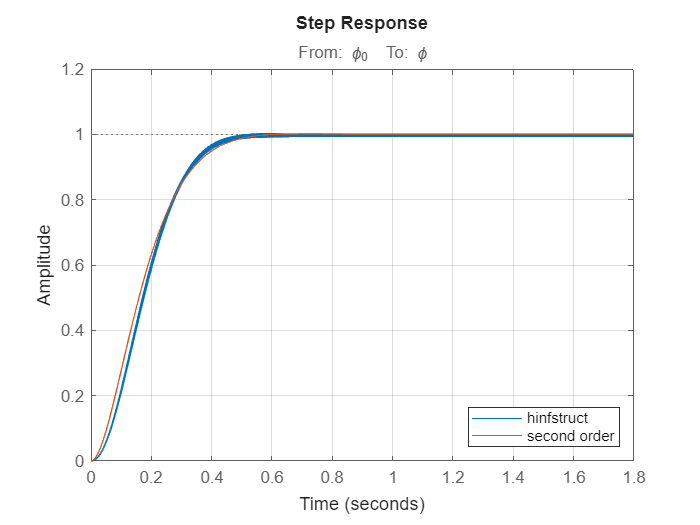

figure
step(F)
hold on
step(F_2)
grid on
legend('hinfstruct','second order', 'location','southeast')

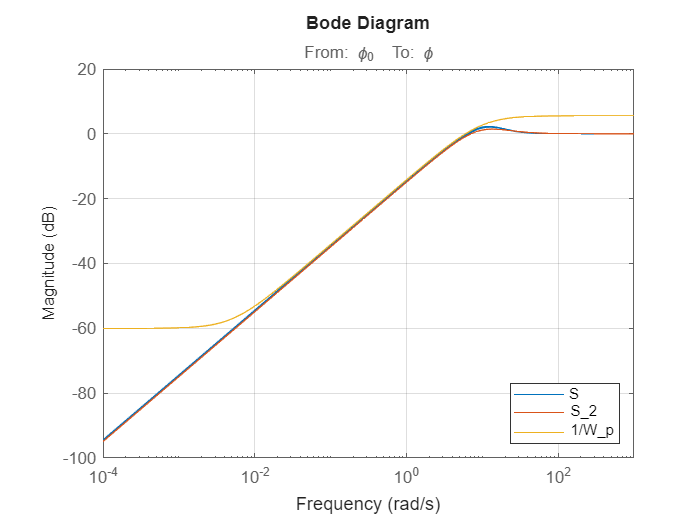

figure
bodemag(S)
hold on
grid on
bodemag(S_2)
bodemag(1/W_p)
legend('S', 'S_2','1/W_p', 'location','southeast')

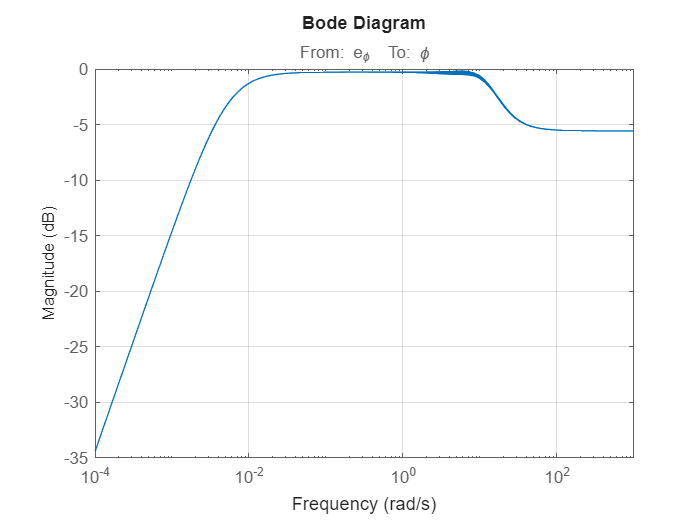


figure
bodemag(S*W_p)
grid on

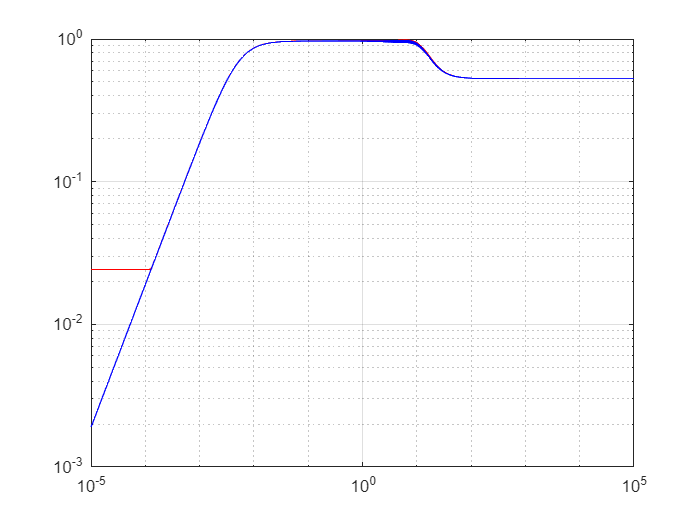


figure
loglog(w, msvd, 'r')
grid on
hold on
SWp = abs(freqresp(S*W_p, w));
for i=1:size(S.A, 3)
    loglog(w, reshape(SWp(:, :, :, i), [], 1), 'b')
end

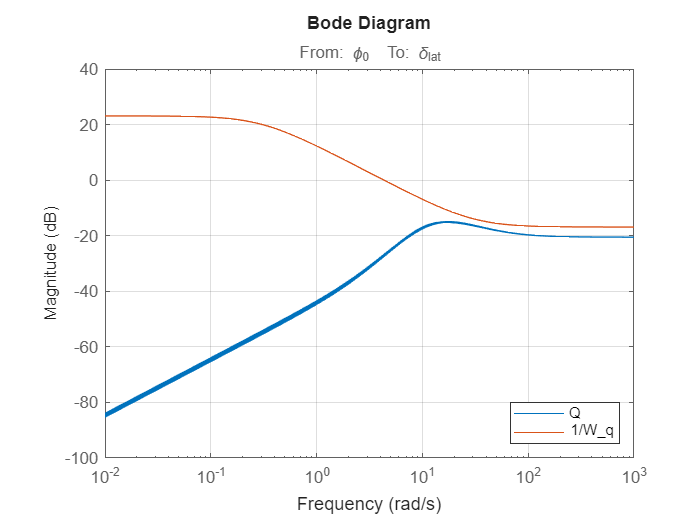

figure
bodemag(Q)
grid on
hold on
bodemag(1/W_q)
legend('Q','1/W_q', 'location','southeast')

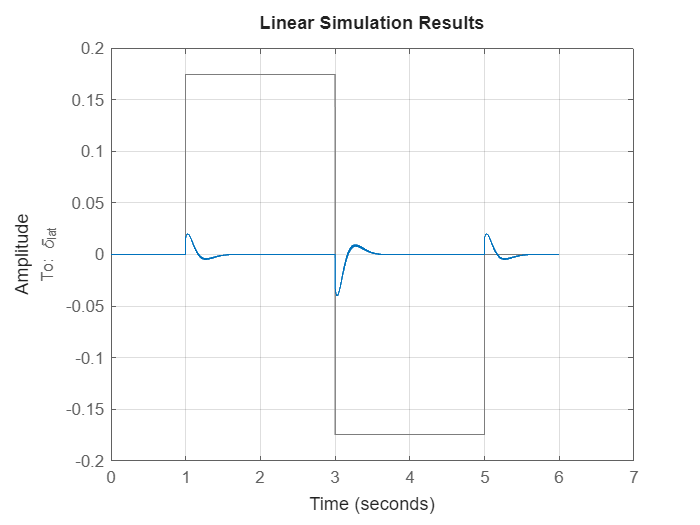

t = linspace(0,6,10^4);
u = 0*(t<=1) + 10*(t>1 & t<= 3) - 10*(t>3 & t<= 5) + 0*(t>5);
u = deg2rad(u);

figure
lsim(Q,u,t);
hold on
grid on

## **9) Montecarlo**

Nmax = 5000;
settling_time_array = [];
overshoot_array = [];
max_effort_array = [];
mean_settling_time = zeros(Nmax, 1);
mean_overshoot = zeros(Nmax, 1);
mean_max_effort = zeros(Nmax, 1);

sigma_Y_v = abs((unc_Y_v/300)*Y_v_nom);
sigma_Y_p = abs((unc_Y_p/300)*Y_p_nom);
sigma_L_p = abs((unc_L_p/300)*L_p_nom);
sigma_Y_d = abs((unc_Y_d/300)*Y_d_nom);
sigma_L_d = abs((unc_L_d/300)*L_d_nom);

for N = 1:Nmax
    
    % Stability Derivatives
    Y_v_sample = normrnd(Y_v_nom,sigma_Y_v);
    Y_p_sample = normrnd(Y_p_nom,sigma_Y_p);
    L_p_sample = normrnd(L_p_nom,sigma_L_p);
    
    % Control Derivatives
    Y_d_sample = normrnd(Y_d_nom,sigma_Y_d);
    L_d_sample = normrnd(L_d_nom,sigma_L_d);

    sample = struct( ...
        'Y_v', Y_v_sample, ...
        'Y_p', Y_p_sample, ...
        'L_p', L_p_sample, ...
        'Y_d', Y_d_sample, ...
        'L_d', L_d_sample);

     sys_sample = usubs(sys_ld, sample);

     SumOuter = sumblk('e_\phi = \phi_0 - \phi');
     CL_sample = connect(R_p, R_phi, sys_sample, SumOuter, W_q, W_p, ...
        '\phi_0',{'z_1','z_2'},{'\delta_{lat}','e_\phi','\phi'});
    
     F_sample = getIOTransfer(CL_sample,'\phi_0','\phi');
     Q_sample = getIOTransfer(CL_sample,'\phi_0','\delta_{lat}');
    
     % NOMINAL PERFORMANCE
     sample_info = stepinfo(F_sample);

     settling_time_array = [settling_time_array,sample_info.SettlingTime];
     mean_settling_time(N) = mean(settling_time_array(1:N));

     overshoot_array = [overshoot_array,sample_info.Overshoot];
     mean_overshoot(N) = mean(overshoot_array(1:N));
     
     % CONTROL EFFORT
     max_effort_sample = max(abs(lsim(Q_sample,u,t)));
     max_effort_array = [max_effort_array,max_effort_sample];
     mean_max_effort(N) = mean(max_effort_array(1:N));

end   


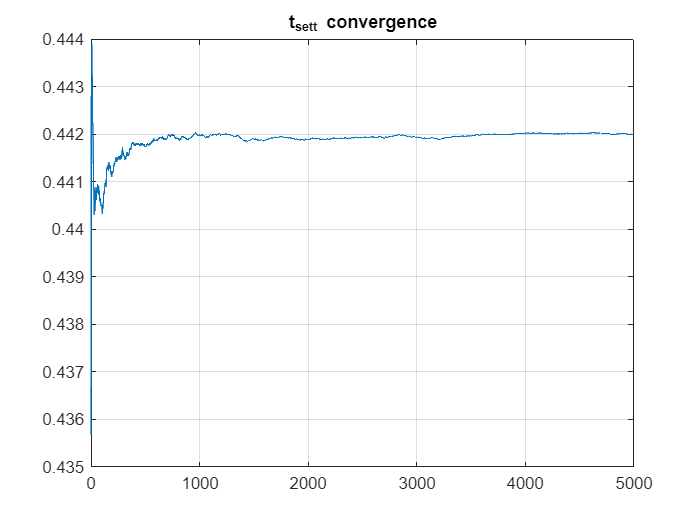

figure
plot(cumsum(settling_time_array)./(1:length(settling_time_array)));
grid on
title('t_{sett} convergence')


mean_settling_time = mean(settling_time_array)

mean_settling_time = 0.4420

std_dev_settling_time = std(settling_time_array)

std_dev_settling_time = 0.0056

failure_count_settling_time = sum(settling_time_array>0.47)

failure_count_settling_time = 0

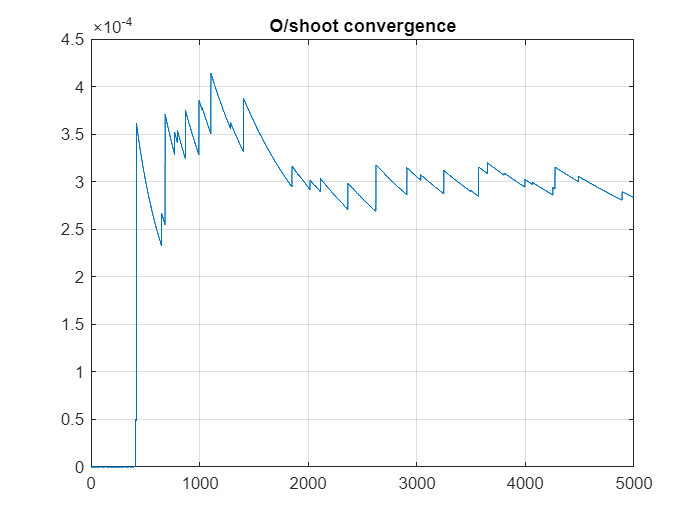


figure
plot(cumsum(overshoot_array)./(1:length(overshoot_array)));
grid on
title('O/shoot convergence')


mean_overshoot = mean(overshoot_array)

mean_overshoot = 2.8415e-04

std_dev_overshoot = std(overshoot_array)

std_dev_overshoot = 0.0045

failure_count_overshoot = sum(overshoot_array>0.1524)

failure_count_overshoot = 0

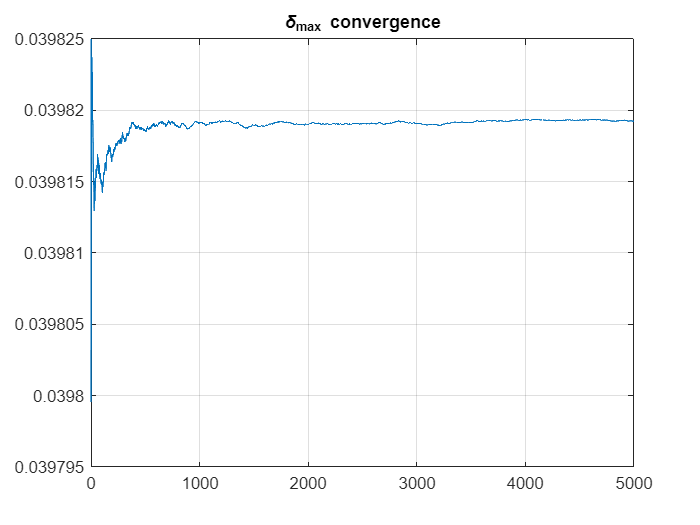


figure
plot(cumsum(max_effort_array)./(1:length(max_effort_array)));
grid on
title('\delta_{max} convergence')


mean_delta_max = mean(max_effort_array)

mean_delta_max = 0.0398

std_dev_delta_max = std(max_effort_array)

std_dev_delta_max = 1.9845e-05

failure_count_max_effort = sum(max_effort_array>0.05)

failure_count_max_effort = 0

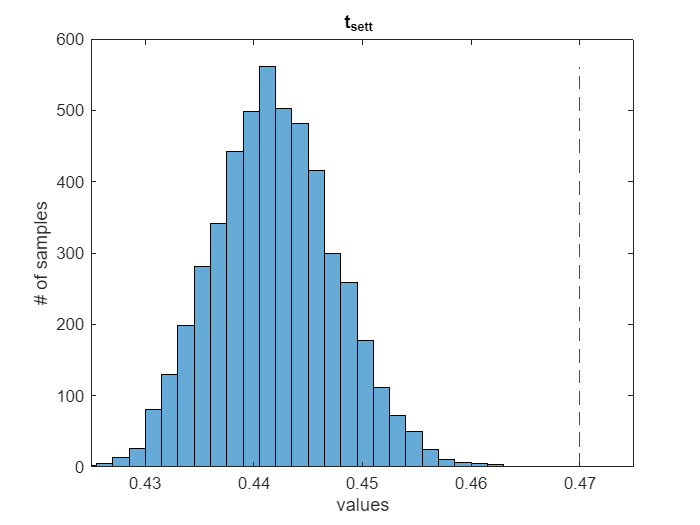

figure
h = histogram(settling_time_array, 30);
hold on
plot([0.47 0.47], [0, max(h.Values)], 'r--')
xlim([0.425 0.475])
title('t_{sett} ')
xlabel('values')
ylabel('# of samples')

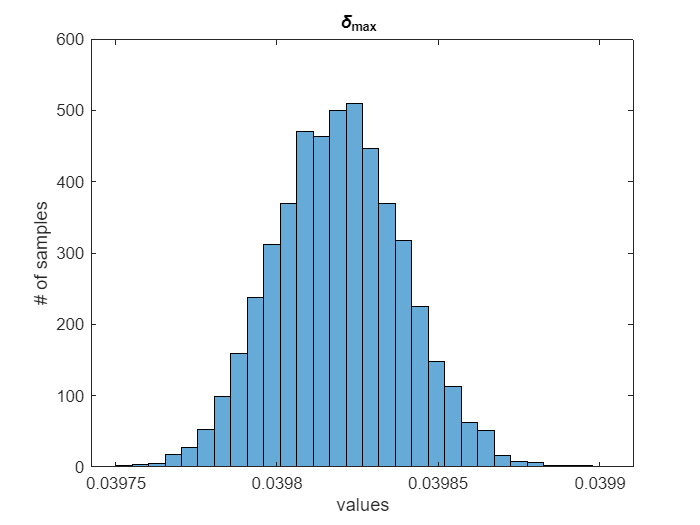


figure
h = histogram(max_effort_array, 30);
title('\delta_{max} ')
xlabel('values')
ylabel('# of samples')

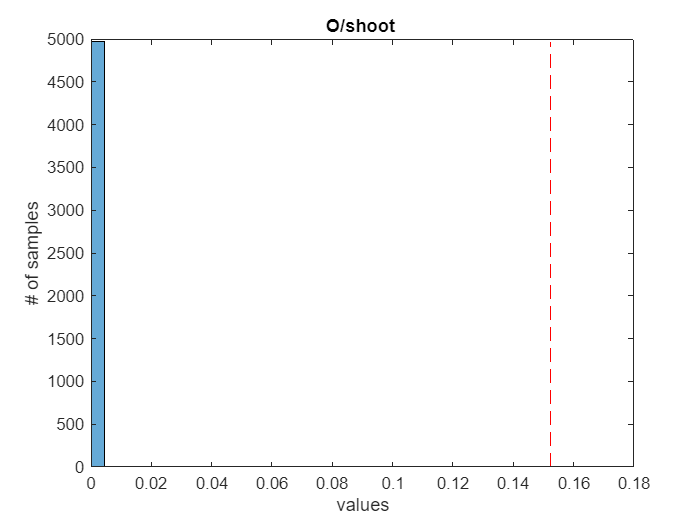



figure
h = histogram(overshoot_array, 30);
hold on
plot([0.1524 0.1524], [0, max(h.Values)], 'r--')
xlim([0 0.18])
title('O/shoot ')
xlabel('values')
ylabel('# of samples')

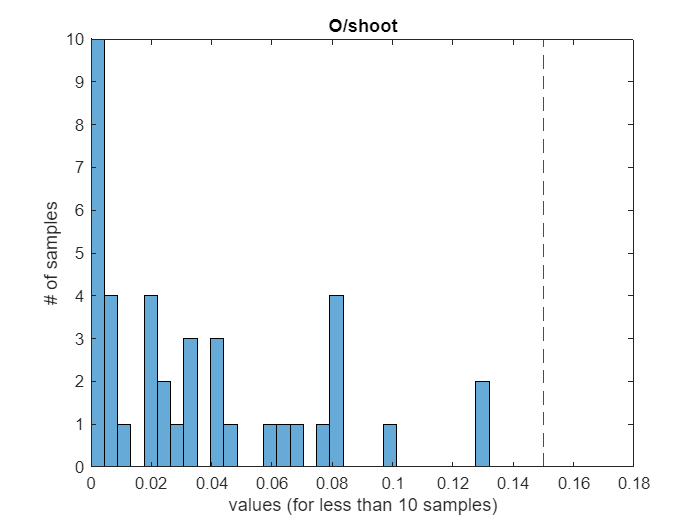


figure
h = histogram(overshoot_array, 30);
hold on
plot([0.15 0.15], [0, max(h.Values)], 'r--')
ylim([0, 10])
xlim([0 0.18])
title('O/shoot')
xlabel('values (for less than 10 samples)')
ylabel('# of samples')